set(0,'DefaultTextFontname', 'LM Roman 9')
set(0,'DefaultAxesFontName', 'LM Roman 9')

pidx = [16,3];

preds_path = "C:\.matlab_workspace\.data\raw_preds\";
truth_path = "C:\.matlab_workspace\.data\ct_pt_volumes_fixed\";

truth = load(truth_path + "patient" + pidx(1) + "_day" + pidx(2) + ".mat", "spine_mask");
truth = truth.spine_mask;
truth = logical(truth);
axial_pred = load(preds_path + "axial_multiclass\" + "patient" + pidx(1) + "_day" + pidx(2) + "_axial.mat", "spine");
axial_pred = axial_pred.spine;
axial_pred = axial_pred > 0.5;
sagittal_pred = load(preds_path + "sagittal_multiclass\" + "patient" + pidx(1) + "_day" + pidx(2) + "_sagittal.mat", "spine");
sagittal_pred = sagittal_pred.spine;
sagittal_pred = sagittal_pred > 0.5;
coronal_pred = load(preds_path + "coronal_multiclass\" + "patient" + pidx(1) + "_day" + pidx(2) + "_coronal.mat", "spine");
coronal_pred = coronal_pred.spine;
coronal_pred = coronal_pred > 0.5;

additive_pred = axial_pred + sagittal_pred;
additive_pred = additive_pred > 0;

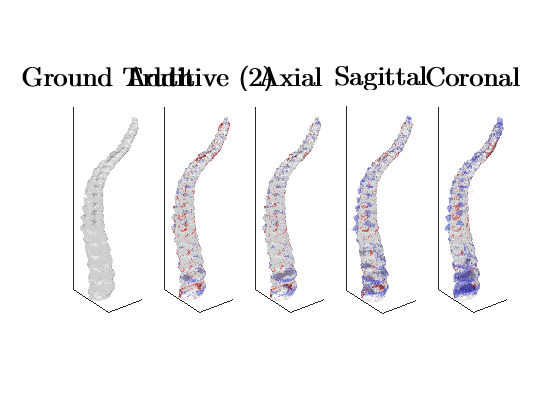

figure();
subplot(1, 5, 1);
pred_vol = truth;
intersection = pred_vol .* truth;
false_neg_vol = truth - intersection;
false_pos_vol = pred_vol - intersection;
fv0 = isosurface(pred_vol, .9);
fv1 = isosurface(false_neg_vol, .9);
fv2 = isosurface(false_pos_vol, .9);
p0 = patch(fv0, 'FaceColor', 'black', 'CDataMapping', 'scaled', 'EdgeColor','none');
p0.FaceAlpha = .1;
p1 = patch(fv1, 'FaceColor', 'blue', 'CDataMapping', 'scaled', 'EdgeColor','none');
p1.FaceAlpha = .2;
p2 = patch(fv2, 'FaceColor', 'red', 'CDataMapping', 'scaled', 'EdgeColor','none');
p2.FaceAlpha = .4;
view(3)
daspect([1,1,1/3])
axis tight
camlight
camlight(-80,-80)
lighting flat
title("\fontsize{20}Ground Truth")
xlims = get(gca, 'XLim');
ylims = get(gca, 'YLim');
zlims = get(gca, 'ZLim');
set(gca, 'XTickLabel', [], 'YTickLabel', [], 'ZTickLabel', [], ...
         'XTick', [], 'YTick', [], 'ZTick', []);

subplot(1, 5, 2);
pred_vol = additive_pred;
intersection = pred_vol .* truth;
false_neg_vol = truth - intersection;
false_pos_vol = pred_vol - intersection;
fv0 = isosurface(pred_vol, .9);
fv1 = isosurface(false_neg_vol, .9);
fv2 = isosurface(false_pos_vol, .9);
p0 = patch(fv0, 'FaceColor', 'black', 'CDataMapping', 'scaled', 'EdgeColor','none');
p0.FaceAlpha = .1;
p1 = patch(fv1, 'FaceColor', 'blue', 'CDataMapping', 'scaled', 'EdgeColor','none');
p1.FaceAlpha = .2;
p2 = patch(fv2, 'FaceColor', 'red', 'CDataMapping', 'scaled', 'EdgeColor','none');
p2.FaceAlpha = .4;
view(3)
daspect([1,1,1/3])
axis tight
camlight
camlight(-80,-80)
lighting flat
title("\fontsize{20}Additive (2)")
set(gca, 'XLim', xlims, 'YLim', ylims, 'ZLim', zlims, ...
         'XTickLabel', [], 'YTickLabel', [], 'ZTickLabel', [], ...
         'XTick', [], 'YTick', [], 'ZTick', []);

subplot(1, 5, 3);

pred_vol = axial_pred;
intersection = pred_vol .* truth;
false_neg_vol = truth - intersection;
false_pos_vol = pred_vol - intersection;
fv0 = isosurface(pred_vol, .9);
fv1 = isosurface(false_neg_vol, .9);
fv2 = isosurface(false_pos_vol, .9);
p0 = patch(fv0, 'FaceColor', 'black', 'CDataMapping', 'scaled', 'EdgeColor','none');
p0.FaceAlpha = .1;
p1 = patch(fv1, 'FaceColor', 'blue', 'CDataMapping', 'scaled', 'EdgeColor','none');
p1.FaceAlpha = .2;
p2 = patch(fv2, 'FaceColor', 'red', 'CDataMapping', 'scaled', 'EdgeColor','none');
p2.FaceAlpha = .4;
view(3)
daspect([1,1,1/3])
axis tight
camlight
camlight(-80,-80)
lighting flat
title("\fontsize{20}Axial")
set(gca, 'XLim', xlims, 'YLim', ylims, 'ZLim', zlims, ...
         'XTickLabel', [], 'YTickLabel', [], 'ZTickLabel', [], ...
         'XTick', [], 'YTick', [], 'ZTick', []);

subplot(1, 5, 4);
pred_vol = sagittal_pred;
intersection = pred_vol .* truth;
false_neg_vol = truth - intersection;
false_pos_vol = pred_vol - intersection;
fv0 = isosurface(pred_vol, .9);
fv1 = isosurface(false_neg_vol, .9);
fv2 = isosurface(false_pos_vol, .9);
p0 = patch(fv0, 'FaceColor', 'black', 'CDataMapping', 'scaled', 'EdgeColor','none');
p0.FaceAlpha = .1;
p1 = patch(fv1, 'FaceColor', 'blue', 'CDataMapping', 'scaled', 'EdgeColor','none');
p1.FaceAlpha = .2;
p2 = patch(fv2, 'FaceColor', 'red', 'CDataMapping', 'scaled', 'EdgeColor','none');
p2.FaceAlpha = .4;
view(3)
daspect([1,1,1/3])
axis tight
camlight
camlight(-80,-80)
lighting flat
title("\fontsize{20}Sagittal")
set(gca, 'XLim', xlims, 'YLim', ylims, 'ZLim', zlims, ...
         'XTickLabel', [], 'YTickLabel', [], 'ZTickLabel', [], ...
         'XTick', [], 'YTick', [], 'ZTick', []);

subplot(1, 5, 5);
pred_vol = coronal_pred;
intersection = pred_vol .* truth;
false_neg_vol = truth - intersection;
false_pos_vol = pred_vol - intersection;
fv0 = isosurface(pred_vol, .9);
fv1 = isosurface(false_neg_vol, .9);
fv2 = isosurface(false_pos_vol, .9);
p0 = patch(fv0, 'FaceColor', 'black', 'CDataMapping', 'scaled', 'EdgeColor','none');
p0.FaceAlpha = .1;
p1 = patch(fv1, 'FaceColor', 'blue', 'CDataMapping', 'scaled', 'EdgeColor','none');
p1.FaceAlpha = .2;
p2 = patch(fv2, 'FaceColor', 'red', 'CDataMapping', 'scaled', 'EdgeColor','none');
p2.FaceAlpha = .4;
view(3)
daspect([1,1,1/3])
axis tight
camlight
camlight(-80,-80)
lighting flat
title("\fontsize{20}Coronal")
set(gca, 'XLim', xlims, 'YLim', ylims, 'ZLim', zlims, ...
         'XTickLabel', [], 'YTickLabel', [], 'ZTickLabel', [], ...
         'XTick', [], 'YTick', [], 'ZTick', []);